# SISTEMES d'EQUACIONS (SESSIÓ 8)

## 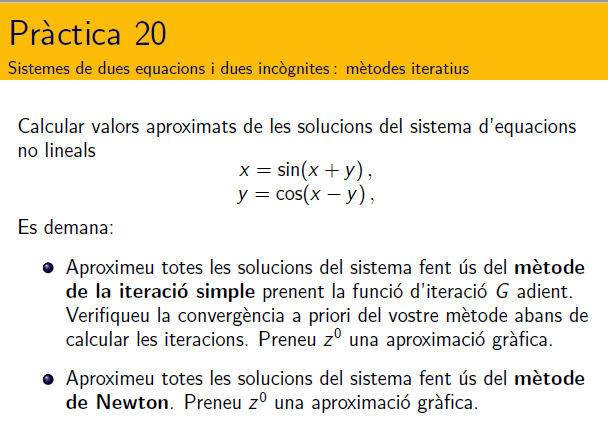

## Método del punto fijo

**Método del punto fijo con control del error y del número de iteraciones**

Matriz jacobiana de la función d'iteración calculada en Symbolic Math Toolbox

%%---SymbolicMathToolbox------------------------------------------------------------
syms x y
G(x,y)=[sin(x+y); cos(x-y)]                % Función de iteración
JG(x,y)=jacobian(G(x,y),[x,y])             % Matriz jacobiana de la función de iteración
Z0=[1;0.9]
control=JG(Z0(1),Z0(2)); 
control2=norm(control,1); 
criteriTEOREMA=vpa(control2,8)
%%----Aritmética de punto flotante------------------------------------------------------
clear x y G(x,y) JG(x,y)
if criteriTEOREMA >=1 
    error('método divergente')
else
    disp('método convergente')
    G=@(x,y)[sin(x+y); cos(x-y)];
    F=@(x,y)[x-sin(x+y); y-cos(x-y)];
    %---- función itera2d
    alpha = itera2d(G,F,Z0,25,0.5*10^(-7));
end

## Método de Newton

Criterio con control del error y del número de iteraciones

clearvars; format short g;

Z0=[1;0.9] 

Z0 =             1
          0.9


F=@(x,y)[x-sin(x+y); y-cos(x-y)]; F(Z0(1),Z0(2))

ans =        0.0537
    -0.095004


DF=@(x,y)[1-cos(x+y), -cos(x+y); sin(x-y), 1-sin(x-y)]; DF(Z0(1),Z0(2))

ans =        1.3233      0.32329
     0.099833      0.90017


tolZ=0.5*10^(-7);
tolF= 0.5*10^(-7); 
Nmax=10;
%----función newton2d
alpha = newton2d(F,DF,Z0,Nmax,tolF,tolZ);


solución = 0.93508     0.99802
tolF = 2.2204e-16
tolZ = 1.2616e-08
iteraciones = 4



alpha = newton2Mod(F,DF,Z0,Nmax,tolF,tolZ)

alpha =       0.93508
      0.99802


alpha = jacobi2V(F,DF,Z0,Nmax,tolF,tolZ)

alpha =       0.93508
      0.99802


alpha = gaussSeidel2(F,DF,Z0,Nmax,tolF,tolZ)

alpha =       0.93508
      0.99802


p= -2;
w=1/(1+p)

w =     -1


alpha = SOR2(F,DF,Z0,p,Nmax,tolF,tolZ)

alpha =       0.93508
      0.99802
